## Load Data

Data was recorded using the Ripple system, and it was saved as a `.ns2` file. I am using a script written by Tyler to import the image into a MATLAB-readable format.

[head, data] = read_nsx_file('File', 'D:\FRM\research-data\emg-fatigue\datafile0022.ns5');

Loading 1.2 GB of data


## Extract Channel Data and Metadata

fs = head.Fs;
ch_idx = 1;
ch_signal = data(ch_idx, :);
fprintf("Data from channel %02d sampled at %d kHz.\n%.3f sec (%02.0f mins) total.", ch_idx, fs, length(ch_signal)/fs,length(ch_signal)/fs/60);

Data from channel 01 sampled at 30000 kHz.
600.882 sec (10 mins) total.

## Extract Power Spectrum Information

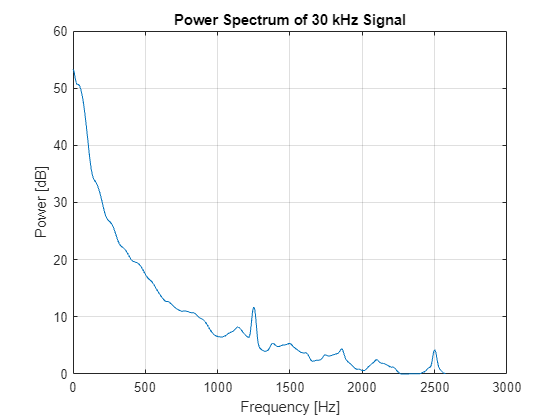

[Fch_signal, Pch_signal] = compute_db_spectrum(ch_signal, fs);
idx_cond = Pch_signal > 0;

plot(Fch_signal(idx_cond), Pch_signal(idx_cond))
grid on
title("Power Spectrum of 30 kHz Signal")
xlabel("Frequency [Hz]")
ylabel("Power [dB]")

## Remove Baselines

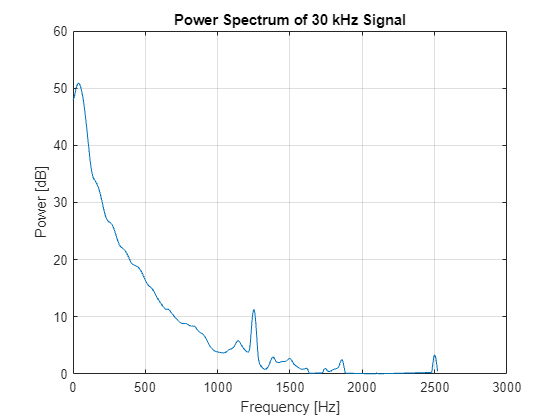

idx_start = 35*fs; 
idx_stop = length(ch_signal) - 35*fs;
ch_signal_trunc = ch_signal(idx_start:idx_stop);

[ch_signal_trunc_freq, ch_signal_trunc_pow] = compute_db_spectrum(ch_signal_trunc, fs);
idx_cond = ch_signal_trunc_pow> 0;

plot(ch_signal_trunc_freq(idx_cond), ch_signal_trunc_pow(idx_cond))
grid on
title("Power Spectrum of 30 kHz Signal")
xlabel("Frequency [Hz]")
ylabel("Power [dB]")

## Decimate the Signal to 1 kHz

dec_factor = 30;
fs = head.Fs/dec_factor

fs = 1000

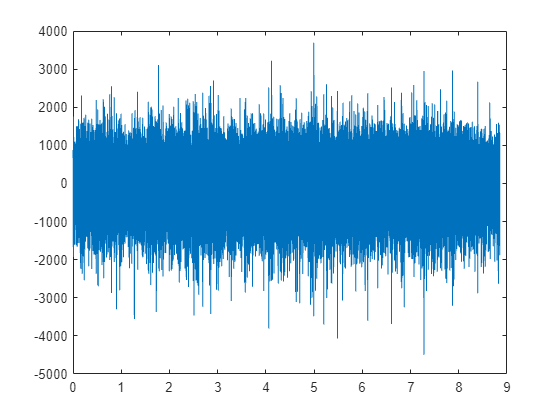

ch_signal_dec = decimate(double(ch_signal_trunc), dec_factor);

plot([0:length(ch_signal_dec)-1]/fs/60, ch_signal_dec)

## Apply bandpass filter to signal

This should not change anything since the Ripple device already filters the data between 15 Hz and 375 Hz (**Check your settings**).

If you decide to apply a filter anyway, use `filtfilt()` to avoid introducing phase shifting.

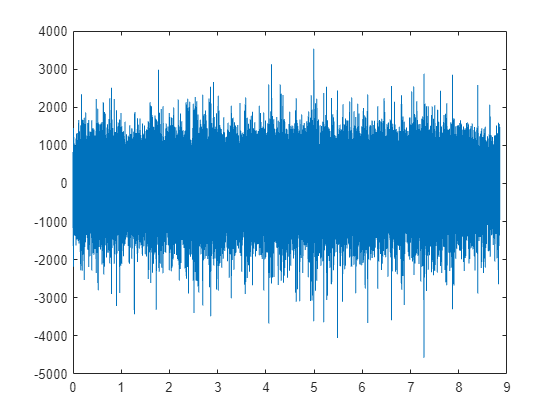

filt_order = 5;
f_nyq = fs /2;
fc_1 = 5;
fc_2 = 499;
[b, a] = butter(filt_order, [fc_1, fc_2]/f_nyq, 'bandpass');
ch_signal_filt = filtfilt(b, a, double(ch_signal_dec));

plot([0:length(ch_signal_filt)-1]/fs/60, ch_signal_filt)

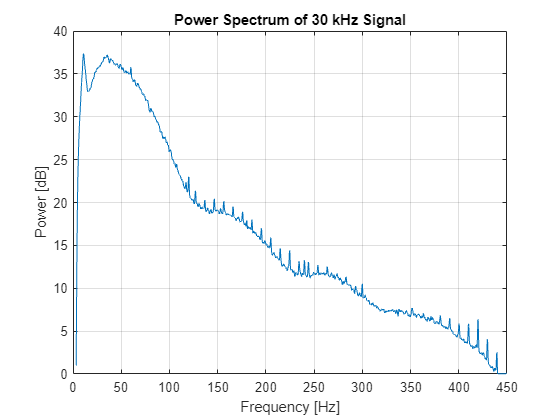

[ch_signal_trunc_freq, ch_signal_trunc_pow] = compute_db_spectrum(ch_signal_filt, fs);
idx_cond = ch_signal_trunc_pow> 0;

plot(ch_signal_trunc_freq(idx_cond), ch_signal_trunc_pow(idx_cond))
grid on
title("Power Spectrum of 30 kHz Signal")
xlabel("Frequency [Hz]")
ylabel("Power [dB]")

sig_len = length(ch_signal_filt);
win_len = 100*fs;
ovr_len = win_len-1;

n_win = floor((sig_len-ovr_len)/(win_len-ovr_len));
ch_mdf = zeros(n_win, 1);

parfor i = 1:n_win
    idx_start = i;
    idx_stop = i+ovr_len;
    try
    win_data = ch_signal_filt(idx_start:idx_stop);
    ch_mdf(i) = medfreq(win_data, fs);
    catch
        disp(idx_stop)
    end
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 12).


x = [1:length(ch_mdf)]/fs;
plot(x,ch_mdf)
hold on
mdf_poly = polyfit(x, ch_mdf, 1)

mdf_poly =    -0.0069   44.7084


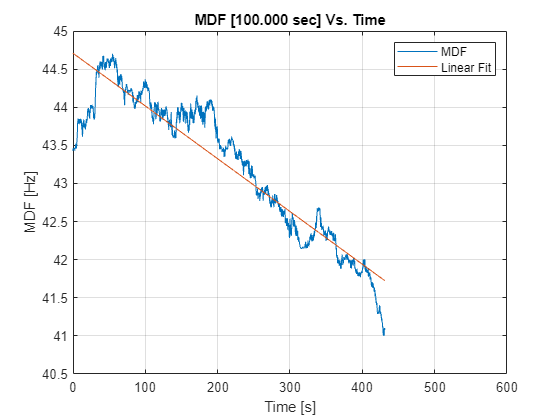

plot(x, polyval(mdf_poly, x))
hold off

grid on
legend(["MDF","Linear Fit"])

title(sprintf("MDF [%.3f sec] Vs. Time", win_len/fs))
xlabel("Time [s]")
ylabel("MDF [Hz]")
xlim([0 600])

adtest([-0.0071 -0.0075 -0.0072 -0.0073 -0.0081])

ans = logical
   0
